file = readtable('Pendulum Data.xlsx');
t = file{:,1}; % time (seconds)
v = file{:,2}; % voltage (V)

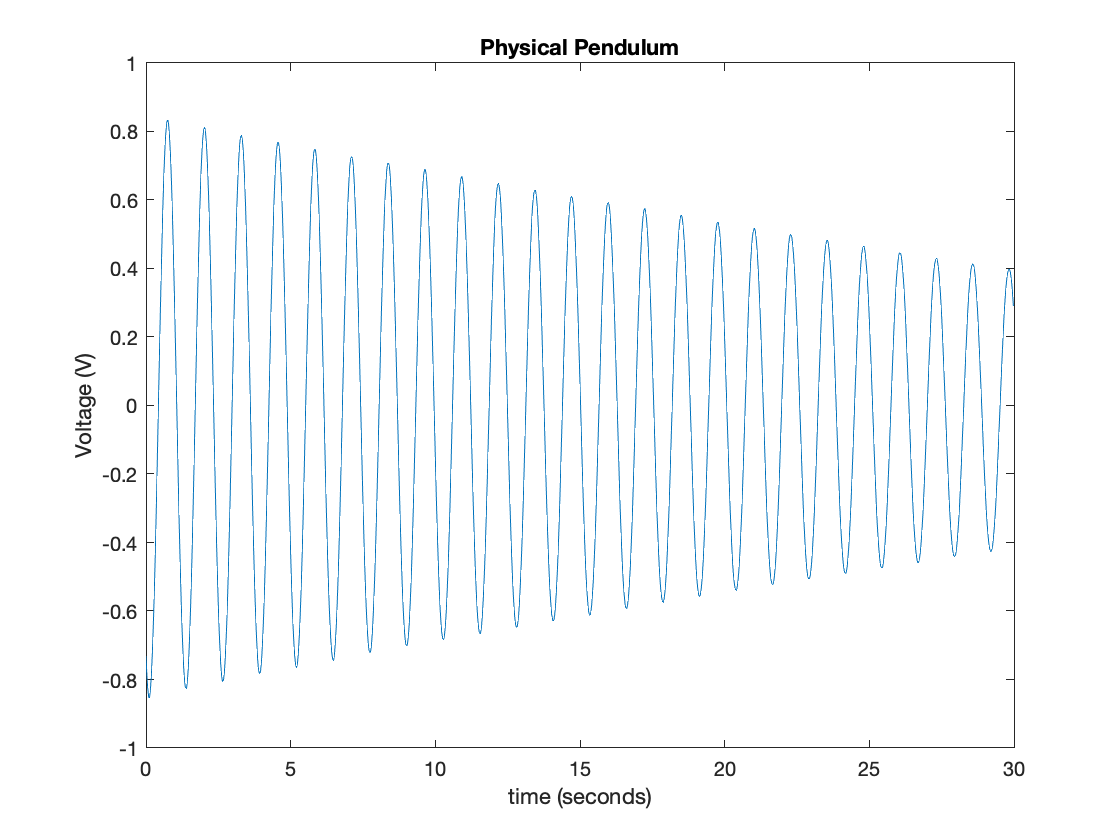

plot(t,v)
title('Physical Pendulum')
xlabel('time (seconds)')
ylabel('Voltage (V)')

Relate voltage drop to angle

A full 360 rotation would correspond to a 10 v drop


$$\theta \left(t\right)=\frac{V\left(t\right)*360\;}{10\;V}$$


theta = (v.*360)./10 %degrees

theta =   -26.3669
  -27.7062
  -28.8855
  -29.7210
  -30.3255
  -30.7344
  -30.7225
  -30.2129
  -29.5077
  -28.6662


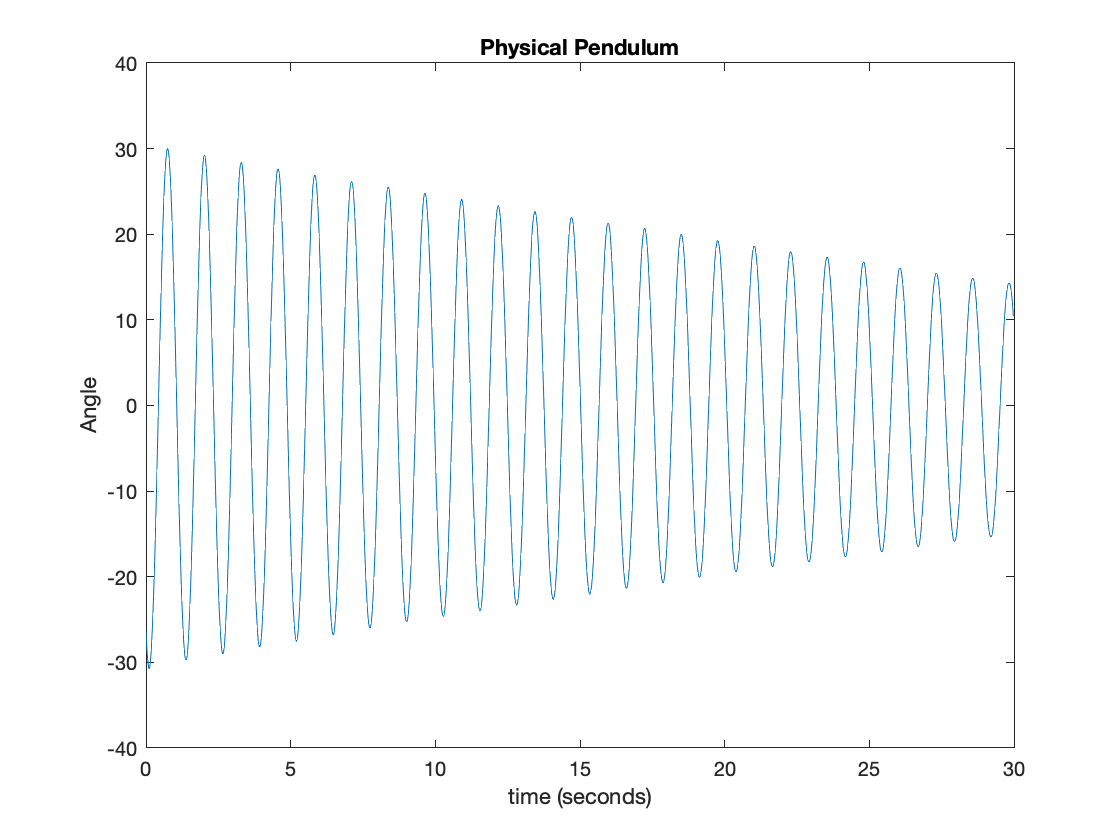

plot(t,theta)
title('Physical Pendulum')
xlabel('time (seconds)')
ylabel('Angle')

Calculate the average period by getting the mean of the distances between peaks

[~,peaklocs] = findpeaks(v, t); % Array of peak locations
 period = mean(diff(peaklocs)) % seconds

period = 1.2643

 frequency = 1/period % Hz

frequency = 0.7909

### Pendulum Equation

Length of pendulum: 45.5 cm = 0.455 m

### 
$$T=2\pi \sqrt{\frac{l}{g}}$$


l = 0.455; % meters
g = 9.81; % meters / second ^2
T = 2*pi*sqrt(l/g)

T = 1.3532